# **Práctica 4: Mejora de los controladores PID implementados en la práctica 3**

Las prácticas de la asignatura control por computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. Las sesiones P3 y P4 se dedican al diseño de controladores PID. Por último, en la práctica P5 se diseñarán controladores en campo frecuencial.

**OBJETIVO: Diseñar un controlador I-P de velocidad de salida para que el sistema de lazo cerrado tenga un error estacionario nulo. Diseñar un controlador I-PD de la posición del eje de salida para la planta estudiada en las sesiones anteriores para que el sistema en lazo cerrado cumpla unas ciertas especificaciones.**

**En esta sesión el estudiante ha de:**

- **Diseñar un I-P y un I-PD por asignación de polos.**

- **Verificar experimentalmente el sistema de control diseñado.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
useExperimentalData = false;

# Ejercicio 14: Diseño e implementación de un I-P por asignación de polos.

Como se puede observar en la práctica 3, al diseñar un controlador PI con una planta de primer orden tienen como respuesta un sistema con dos polos y un cero. Este último, tiene un efecto negativo en la dinámica del sistema, normalmente haciéndola un poco más rápida de lo deseado, es por eso, que obteníamos un pequeño sobreimpulso. Para eliminar el efecto del cero, se propone la siguiente alternativa de introducir las acciones proporcional e integral.

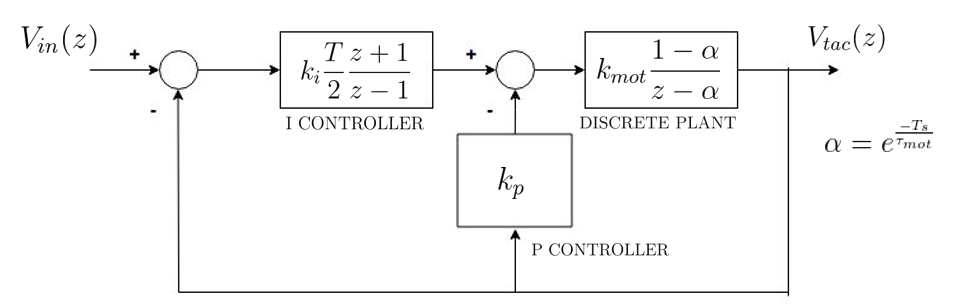

Esta estructura toma el nombre de controlador I-P, y como se puede observar, la acción integral se realimenta desde el error, mientras que la parte proporcional se realimenta desde la salida, es por esto, que la respuesta a un escalón del sistema con un controlador I-P será más suave que la de un sistema con un controlador PI. Como se ha hecho en el P3, se desea diseñar un I-P de control de velocidad que haga que la respuesta temporal a una entrada escalón no presente sobreimpulsos y que el tiempo de establecimiento (con el criterio del 2%) sea de 0.8 segundos. Para la simulación del controlador I-P digital, abrir y ejecutar el modelo P4_Ex14a.slx. Para su comprobación con el motor, abrir y ejecutar el modelo P4_Ex14b.slx.

% Planta
K0=0.82;
tau0=0.26;

% Periodo de muestreo
Ts=0.01;

% Especificaciones
xi=1;
ts_2=0.8; % tiempo de establecimiento con el criterio de 2%
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Diseño del controlador
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

Para diseñar el controlador, se han seguido los siguientes pasos. Primeramente, se ha digitalizado la planta con un mantenedor de orden cero y se ha escogido un controlador PI discretizado mediante la aproximación trapezoidal.


$$\mathrm{motor}:G\left(z\right)=k_{\mathrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\;\;\;\mathrm{donde}\;\;\;\;\;\;\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\mathrm{controlador}\;\mathrm{PI}:\mathrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\mathrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


En este caso, la función de transferencia de lazo cerrado:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{IP}\left(z\right)G\left(z\right)}{1+\mathrm{IP}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+1\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


En el caso del PI la función de transferencia de lazo cerrado era:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{PI}\left(z\right)G\left(z\right)}{1+\mathrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


Como podemos observar, al fijar los polos mediante las ganancias del controlador, automáticamente se fija el cero de lazo cerrado. Sin embargo, si analizamos el cero de la arquitectura del I-P, podemos ver como el cero se fija en z=-1. Vale la pena comentar que la acción proporcional del controlador de IP no ve la referencia, por lo que la respuesta del sistema de lazo cerrado a una entrada por escalón de un controlador del IP es más suave que la del PI.

Como el denominador de lazo cerrado es el mismo que el obtenido en la práctica 3, las ecuaciones utilizadas para ajustar los parámetros del controlador son exactamente las mismas que las utilizadas para el controlador PI.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


Con lo cual, las ecuaciones de sintonía serían:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


Las respuestas ideal y real del controlador I-P se pueden observar en la siguiente imagen.

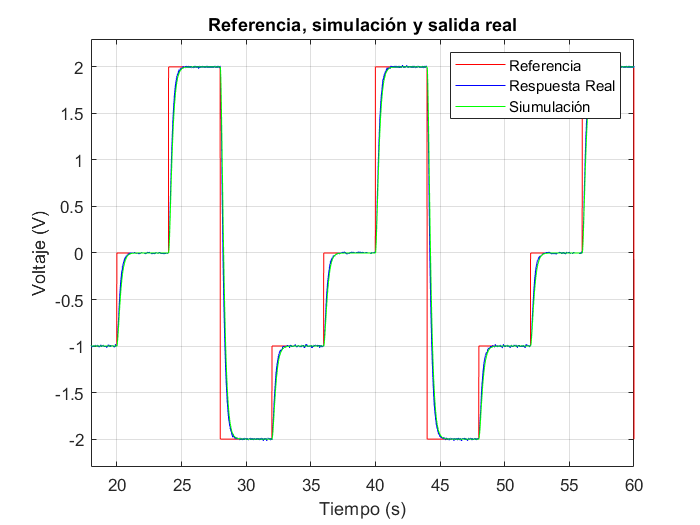

% Dibujar la respuesta del motor
if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'IPvel']);
    open IP_experimental.slx;
    run IP_experimental.slx;
else
    FileName   = 'IP_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);  
    
    FileName   = 'IP_real.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);  
end

figure
plot(IP_ideal.time,[IP_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IP_real.time,[IP_real.signals.values(:,2,:)],'b')
plot(IP_ideal.time,[IP_ideal.signals.values(:,2,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Referencia, simulación y salida real');
legend('Referencia','Respuesta Real','Siumulación');

Como se puede analizar, las dos respuestas son prácticamente iguales y con lo cual, el sistema real cumple las especificaciones deseadas.

# Ejercicio 15: Diseño e implementación de un I-PD por asignación de polos.

Como se puede observar en la práctica 3, al diseñar un controlador PID con una planta de segundo orden tienen como respuesta un sistema con cuatro polos y tres cero. Para poder diseñar un controlador PID donde se cumplan las especificaciones, hay que hacer dos modificaciones principales, la primera, añadir un nuevo parámetro al controlador para poder fijar los cuatro polos del sistema, y el segundo, modificar la estructura para eliminar el efecto de los ceros.

Con lo cual, el nuevo controlador, tendrá la siguiente estructura:


$$\textrm{controlador}\;\textrm{PI}\mathrm{D}:\mathrm{P}\textrm{ID}\left(z\right)=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z+\alpha }\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$


Para eliminar el efecto de los ceros, se propone la siguiente alternativa de introducir las acciones proporcional, integral y derivativa.

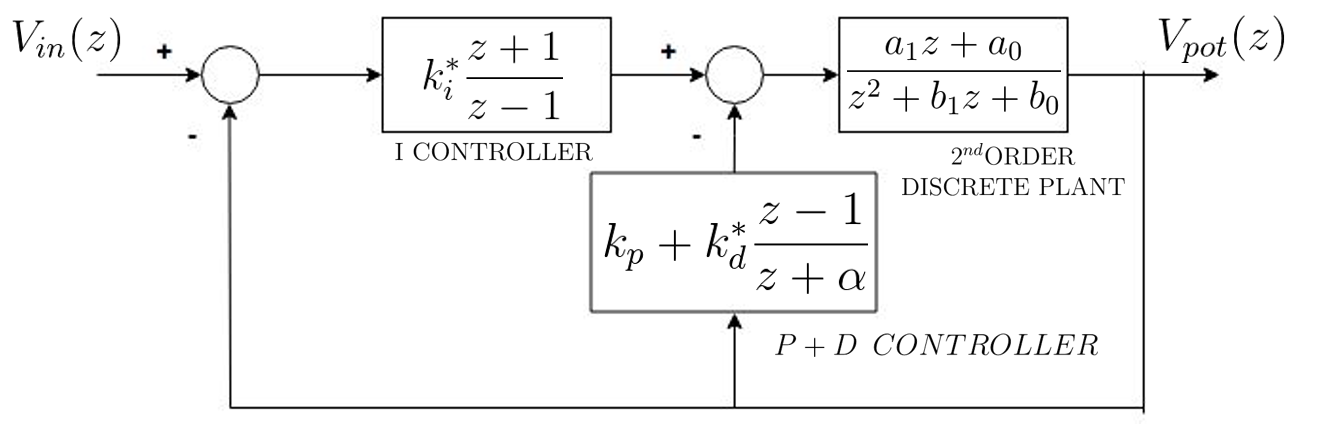

Esta estructura toma el nombre de controlador I-PD, y como se puede observar, la acción integral se realimenta desde el error, mientras que las acciones proporcional y derivativa se realimentan desde la salida.

En este ejercicio se desea diseñar un I-PD de control de posición que haga que la respuesta temporal a una entrada escalón presente un sobreimpulso del 80% y una frecuencia de oscilación de 0,5 Hz.

Toma el periodo de muestreo Ts igual a 0,01s. Determinar el valor de $k_p$,$\;k_i$ y $k_d$ y $\alpha$. 

% Parámetros de la planta 
K0=0.82/0.017;
tau0=0.26;
N=9;
Kpot=1.62;

% Periodo de muestreo
Ts=0.01;

% Especificaciones de control deseadas
Sp=80; % sobreimpulso
Fd=0.5; % frecuencia

% Polos de segundo orden continuo que cumplirán las especificaciones
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))

xi = 0.0709

wn=wd/ sqrt(1-xi^2)

wn = 3.1495

s1=-xi*wn+j*wd

s1 = -0.2231 + 3.1416i

s2=-xi*wn-j*wd

s2 = -0.2231 - 3.1416i

% Polos de segundo orden discreto que cumpliran las especificaciones
p1=exp(Ts* s1 )

p1 = 0.9973 + 0.0313i

p2=exp(Ts* s2 )

p2 = 0.9973 - 0.0313i

% Insertar el tercer y cuarto polo 
p3=0.8

p3 = 0.8000

p4=0.8

p4 = 0.8000

% Función de transferencia discreta de la planta 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coeficientes del denominador y enumerador 
[Nz ,Dz]= tfdata(Ptaz,'v')

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);

% Definiciones de las matrices A y B
A=[1 a1 0 0; ...
   b1-1 a0 a1 0; 
   b0-b1 0 a0 a1; 
  -b0 0 0 a0] ;
b=[-b1+1-p1-p2-p3-p4; 
   -b0+b1+p1*p2-(-p1-p2)*p3-(-p1-p2-p3)*p4; 
   b0-p1*p2*p3-(p1*p2-(-p1-p2)*p3)*p4; 
   p1*p2*p3*p4] ;

% Controlador 
x=inv(A)*b ; 

alpha=x(1)

alpha = -0.6472

c2=x(2)

c2 = 9.0217

c1=x(3)

c1 = -17.8623

c0=x(4)

c0 = 8.8526

A2=[1 1 1; alpha-1 alpha+1 -2; -alpha alpha 1];
B2=[c2;c1;c0];

x2=inv(A2)*B2;

kp = x2(1)

kp = 0.3994

ki = (2/Ts)*x2(2)

ki = 3.4247

kd = Ts*x2(3)

kd = 0.0861

En el caso de la práctica 3 la función de transferencia obtenida tenía la siguiente estructura:


$$\mathrm{cl}\left(z\right)=\frac{a_1 \left(k_p +k_i^* {+k}_d^* \right)z^3 +\left\lbrack a_1 \left(k_i^* -k_p -2k_d^* \right)+a_0 \left(k_p +k_i^* {+k}_d^* \right)\right\rbrack z^2 +\left\lbrack a_1 k_d^* +a_0 \left(k_i^* -k_p -2k_d^* \right)\right\rbrack z+a_0 k_d^* }{z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 +\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 }$$


Como podemos observar, al fijar los polos mediante las ganancias del controlador, automáticamente se fijan los ceros de lazo cerrado. Las expresiones de los polos de lazo cerrado son los siguientes:


$$z_{1,2} =\frac{-\left(k_i^* -k_p -2k_d^* \right)\pm \sqrt{-4k_d^* \left(k_p +k_i^* {+k}_d^* \right)+{\left(k_i^* -k_p -2k_d^* \right)}^2 }}{2\left(k_p +k_i^* {+k}_d^* \right)}\;,\;z_3 =\frac{a_0 }{a_1 }$$


En el caso del I-PD sin embargo, la función de transferencia de lazo cerrado es la siguiente:


$$\textrm{cl}\left(z\right)=\frac{k_i^* \left(z+1\right)\left(a_1 z+a_0 \right)\left(z+\alpha \right)}{z^4 +\left(b_1 -1+\alpha +k_i^* a_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(b_0 -b_1 +b_1 \alpha -\alpha +k_p a_1 \left(\alpha -1\right)+k_p a_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 \left(\alpha +1\right)+k_d^* a_0 \right)z^2 +\left(-b_0 +b_0 \alpha -b_1 \alpha +k_p a_0 \left(\alpha -1\right)-k_p a_1 \alpha +k_i^* a_0 \left(\alpha +1\right)+k_i^* a_1 \alpha -2k_d^* a_0 +k_d^* a_1 \right)z+k_d^* a_0 +k_i^* a_0 \alpha -k_p a_0 \alpha -b_0 \alpha }$$


Como podemos observar, en este caso, los ceros estan fijados en:


$$z_1 =-1,z_2 =-\alpha ,z_3 =\frac{-a_0 }{a_1 }$$


Para obtener las ecuaciones de sintonía, sin embargo, como podemos ver, la ecuación obtenida no es lineal, con lo cual substituiremos el controlador con la forma canónica del PID y después los relacionaremos con el PID implementado.

La función de transferencia canónica del PID tiene la siguiente forma:


$$\textrm{controlador}\;\textrm{PI}\mathrm{D}:\mathrm{P}\textrm{ID}\left(z\right)=\frac{c_2 z^2 +c_1 z+c_0 }{\left(z-1\right)\left(z+\alpha \right)}$$



$$\mathrm{planta}\;\mathrm{segundo}\;\mathrm{orden}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Con lo cual el denominador de la función de transferencia de lazo cerrado con el controlador canónico toma la forma:


$$\textrm{Den}\left(z\right)=z^4 +\left\lbrack \alpha -1+b_1 +c_2 a_1 \right\rbrack z^3 +\left\lbrack \left(b_1 -1\right)\alpha -b_1 +b_0 +a_1 c_1 +a_0 c_2 \right\rbrack z^2 +\left\lbrack \left(b_0 -b_1 \right)\alpha -b_0 +a_0 c_1 +c_0 a_1 \right\rbrack z+c_0 a_0 -\alpha b_0$$


El polinomio es de orden cuatro, con lo cual tendrá cuatro polos y la ecuación característica será:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


Como es un sistema de cuarto orden y cuatro incógnitas, igualando los coeficientes y representándolo en forma matricial, el sistema en lazo cerrado sería:


$$\left\lbrack \begin{array}{cccc}
1 & a_1  & 0 & 0\\
b_1 -1 & a_0  & a_1  & 0\\
b_0 -b_1  & 0 & a_0  & a_1 \\
-b_0  & 0 & 0 & a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \\
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1-b_1 -p_1 {-p}_2 -p_3 -p_4 \\
b_1 -b_0 +p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \\
b_0 {-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \\
p_1 p_2 p_3 p_4 
\end{array}\right\rbrack$$


Este sistema lineal es fácilmente resoluble utilizando MATLAB. La ecuación es $A\;x=b$, donde $A$ es una matriz $n\;x\;n$ y $b$ es un vector columna con $n$ elementos, entonces, $x=\mathrm{inv}\left(A\right)·b$.

Por último, para obtener los parámetros $k_p {,\;k}_i \;y\;k_d$ obtendremos la relación entre nuestro controlador y el modelo canónico.

Nuestro controlador, se puede representar también de la siguiente manera:


$$\mathrm{P}\textrm{ID}\left(z\right)=\frac{\left(k_p +k_i^* +k_d^* \right)z^2 +\left(k_p \left(\alpha -1\right)+k_i^* \left(\alpha +1\right)-2k_d^* \right)z-k_p \alpha +k_i^* \alpha +k_d^* }{\left(z-1\right)\left(z+\alpha \right)}$$


Con lo cual, igualando los coeficientes y representándolo en forma matricial:


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
\alpha -1 & \alpha +1 & -2\\
-\alpha  & \alpha  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack$$


Como se ha hecho anteriormente, este sistema es fácilmente soluble mediante MATLAB, siendo la solución $x=\textrm{inv}\left(A\right)·b$.

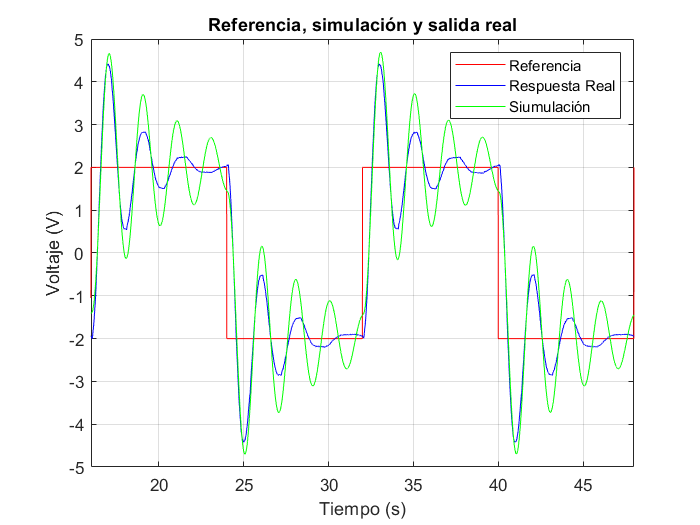

% Dibujar la respuesta del motor
if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'IPDpos']);
    open IPD_real_ideal.slx;
    run IPD_real_ideal.slx;
else
    FileName   = 'IPD_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,2,:)],'b')
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,3,:)],'g')
xlim([16 48]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Referencia, simulación y salida real');
legend('Referencia','Respuesta Real','Siumulación');

Como podemos observar, en este caso, las especificaciones se cumplen en el caso ideal (simulación con el modelo de la planta), pero a la hora de controlar la planta real con esta simulación, podemos observar que, aunque el controlador sea capaz de controlar la planta, las respuestas son bastante distintas. Esto es porque el modelo de la planta no representa fielmente la planta real, ya que hay dinámicas no modeladas.